% compare different correlation source

clearvars; close('all');


% GNSS headng
% load("data\CS_GNSS.mat");
load("data\RT_GNSS.mat");
WatStructG=WatStruct;NavStructG=NavStruct;SensStructG=SensStruct;
% sig compasss
% load("data\CS_SIG.mat"); region='Celtic Sea';
load("data\RT_SIG.mat"); region='Rockall Trough';
WatStructS=WatStruct;NavStructS=NavStruct;SensStructS=SensStruct;


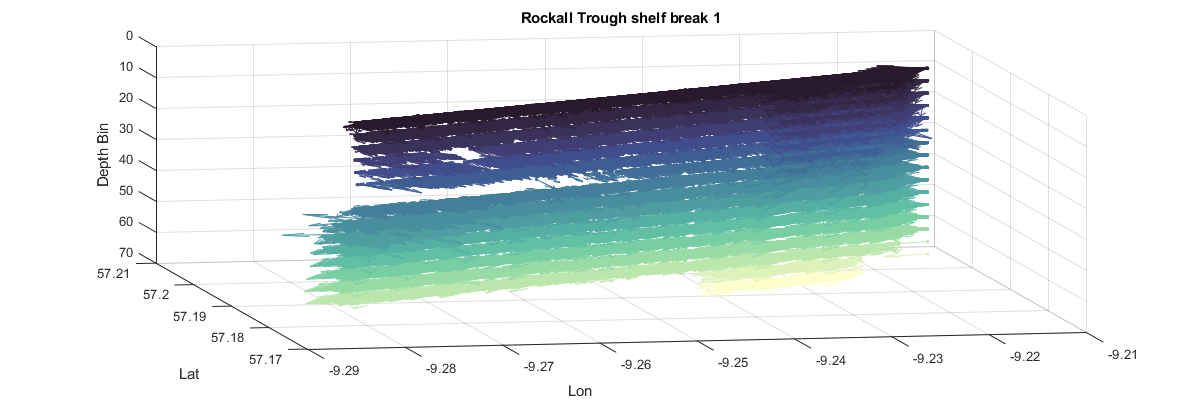

Error using matlab.graphics.chart.primitive.Quiver/set
Error setting property 'MarkerEdgeColor' of class 'Quiver':
Invalid color value.
Error in quiver3 (line 64)
set(h,'Parent',parax,'Color_I',c,'LineStyle_I',ls,pvpairs{:});

clrs=cmocean('-Deep',17);

for mm = 1:numel(WatStructG)

   figure('Renderer', 'painters', 'Position', [10 20 1200 400])
    
   for ii = 1:17
        X=NavStructG(mm).long_deg; X=X';
        X=repmat(X,17,1);
        Y=NavStructG(mm).lat_deg;Y=Y';
        Y=repmat(Y,17,1);
        Z=WatStructG(mm).binDepth;
        U=WatStructG(mm).vEast_ms;
        V=WatStructG(mm).vNorth_ms;
        W=WatStructG(mm).vVert_ms;
    
        Q=quiver3(X(ii,:),Y(ii,:),Z(ii,:),U(ii,:),V(ii,:),W(ii,:),...
            'AutoScaleFactor',12,...
            'LineWidth',0.2,...
            'MaxHeadSize',0.5,...
            "Color",clrs(ii,:),...
            'Marker','.',...
            'MarkerFaceColor','k');
        hold on
    end
        set(gca,'ZDir','reverse')
        view(-11, 22);
%         [az,el] = view
    xlabel('Lon')
    ylabel('Lat')
    zlabel('Depth Bin')
    title([region ' shelf break ' num2str(mm)]) ;
%     print(gcf,'-dpng',['figures/' region '_vec_' num2str(mm)])   
end